### ***2 - a***

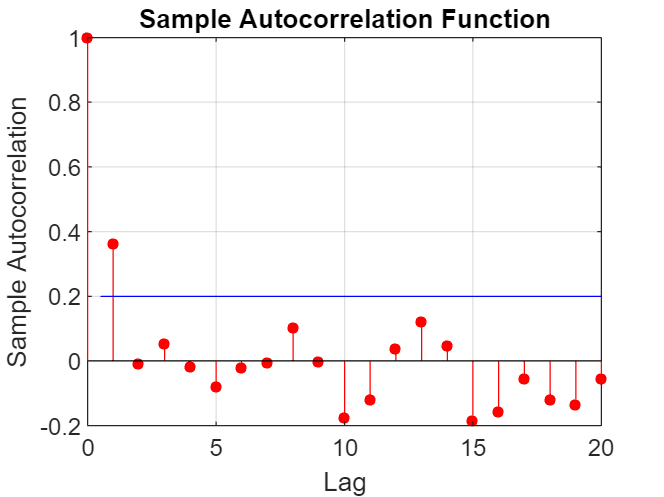

MA1 = arima('Constant',0,'MA',{0.6},'MAlags',[1],'Variance',1);
Y_ma1 = simulate(MA1,100);
autocorr(Y_ma1)

a = autocorr(Y_ma1);
a(1)

ans = 1

a(2)

ans = 0.3617

### ***2 - b***

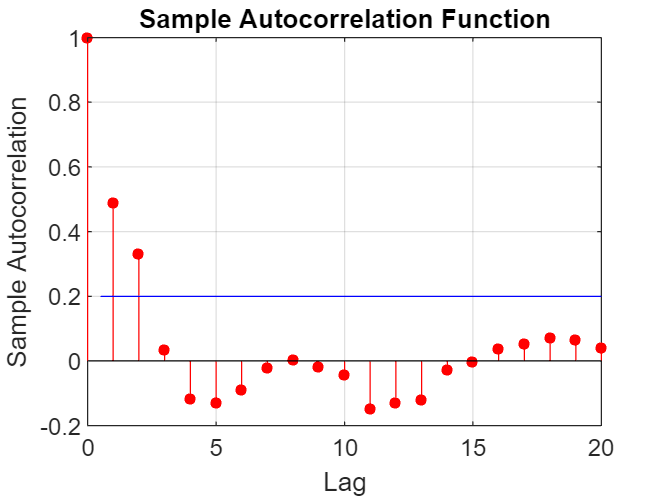

MA2 = arima('Constant',0,'MA',{0.6,0.4},'MAlags',[1,2],'Variance',1);
Y_ma2 = simulate(MA2,100,'NumPaths',100);
autocorr(Y_ma2(:,1))

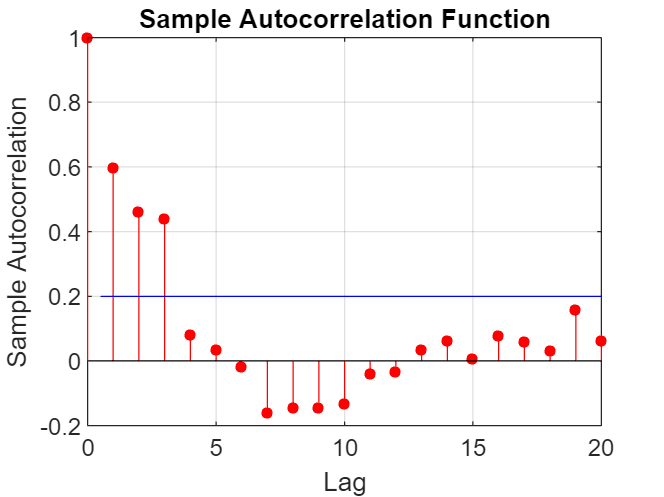

MA3 = arima('Constant',0,'MA',{0.6,0.4,0.7},'MAlags',[1,2,3],'Variance',1);
Y_ma3 = simulate(MA3,100,'NumPaths',100);
autocorr(Y_ma3(:,1))

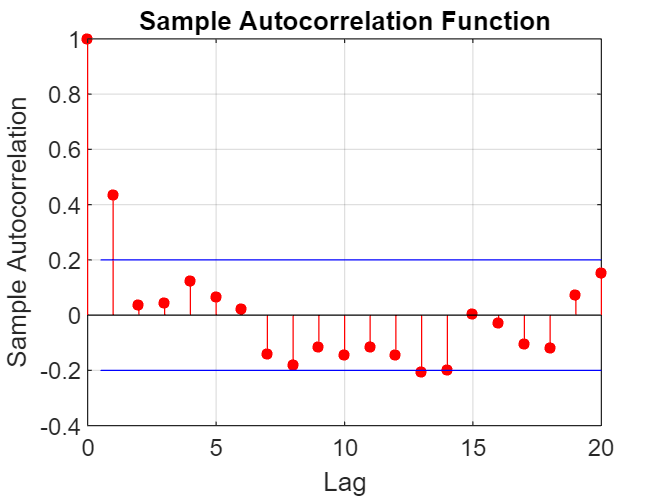

MA7 = arima('Constant',0,'MA',{0.6,0.02,0.01,0.2,0.05,0.1,0.2},'MAlags',[1,2,3,4,5,6,7],'Variance',1);
Y_ma7 = simulate(MA7,100,'NumPaths',100);
autocorr(Y_ma7(:,1))

### ***2 - c***

R = 1000;
MA = arima('Constant',0,'MA',{0.6},'MAlags',[1],'Variance',1);
Y_ma = simulate(MA,100000,'NumPaths',R);
b = zeros(2,R);
for i = 1:R
    c = autocorr(Y_ma(:,i));
    b(1,i) = (c(2));
    b(2,i) = (c(3));
end    
bias = mean(b,2)

bias =     0.4411
    0.0001


v = var(b,0,2)

v = 1.0e-03 *

    0.0577
    0.1366


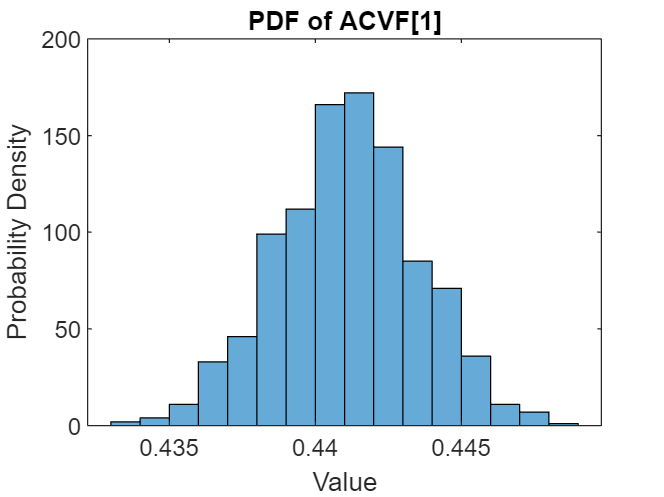

figure;
histogram(b(1,:), 'Normalization', 'pdf');
title('PDF of ACVF[1]');
xlabel('Value');
ylabel('Probability Density');

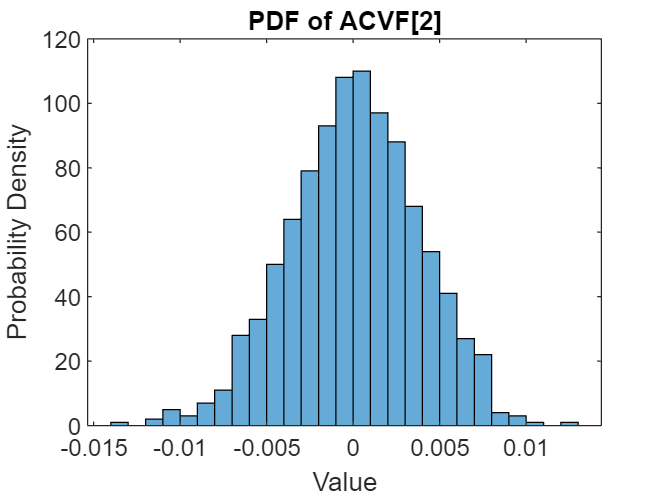

figure;
histogram(b(2,:), 'Normalization', 'pdf');
title('PDF of ACVF[2]');
xlabel('Value');
ylabel('Probability Density');